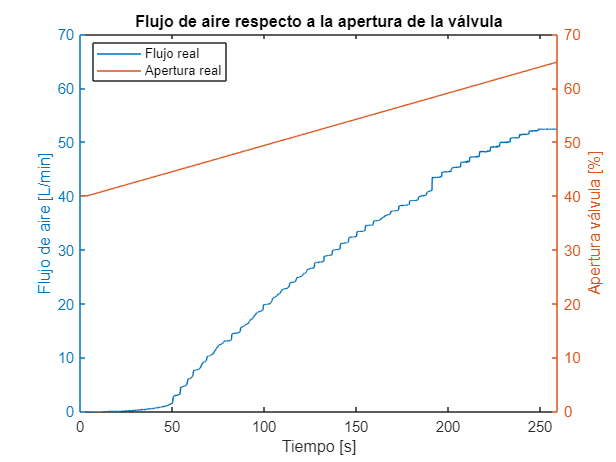

clear all; 
close all;
datos=readmatrix('C:\Users\lucas\Desktop\INGENIERIA INDUSTRIAL\TFG\Laboratorio\ventilator-com-server-main\src\csv_logs\Valvula\Cada0.1%\PROGRAMADO\sensor_data_2023_3_5_11_0_400MBAR.csv');
datos(:,7)=datos(:,7)-datos(1,7);
tiempos=zeros(length(datos),1);
for k=1:length(datos)-1
    tiempos(k+1,1)=tiempos(k,1)+(datos(k+1,7)-datos(k,7));
end
tiempos=tiempos/1000;
t=tiempos;
tam=1:0.1:64.8;
sal=zeros(length(tam),1);
ent=zeros(length(tam),1);
l=1;
for k=1:0.1:64.8
    if k<41
        sal(l)=0;
    else
        I=find(abs(datos(:,5)-k)<0.01);
        sal(l)=mean(datos(I,3));
    end
    ent(l)=k;
    l=l+1;
end
figure()
yyaxis left;
plot(t,datos(:,3))
ylim([0 70])
xlim([0 t(end)])
ylabel('Flujo de aire [L/min]')
yyaxis right;
plot(t,datos(:,5))
ylim([0 70])
xlim([0 t(end)]);
ylabel('Apertura válvula [%]')
xlabel('Tiempo [s]')
title('Flujo de aire respecto a la apertura de la válvula')
legend('Flujo real','Apertura real','Location','best')

n=1;
 I=find(sal>=52.34,1);
ent(I)

ans = 63.9000

I=find(ent>45);
ent=ent(I:end);
sal=sal(I:end);
% ent=ent(41:end);
% sal=sal(41:end);
P=polyfit(ent,sal,1)    %Esta es la recta que linealiza la valvula

P =     2.4595 -102.1576


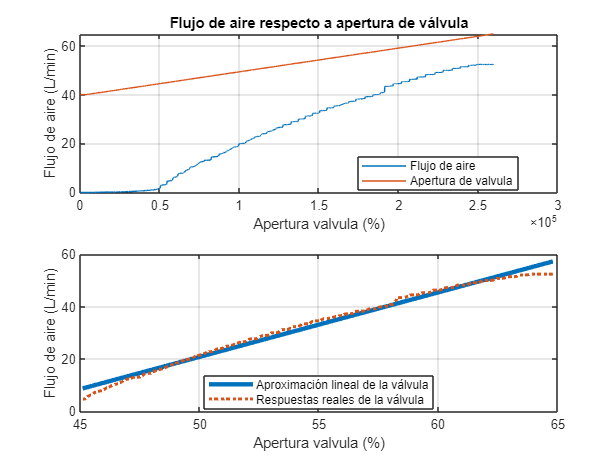

y=polyval(P,ent);
figure()
subplot(2,2,1:2)
plot(datos(:,7),[datos(:,3) datos(:,5)])
title('Flujo de aire respecto a apertura de válvula')
xlabel('Apertura valvula (%)')
ylabel('Flujo de aire (L/min)')
legend('Flujo de aire','Apertura de valvula','Location','best')
grid;
%La zona muerta es hasta una apertura de valvula del 45%
subplot(2,2,3:4)
plot(ent,y,'LineWidth',3)
hold on;
plot(ent,sal,':','LineWidth',2)
xlabel('Apertura valvula (%)')
ylabel('Flujo de aire (L/min)')
legend('Aproximación lineal de la válvula','Respuestas reales de la válvula','Location','best')
grid;
hold off;

incrementoU=max(ent)-min(ent);

Unrecognized function or variable 'ent'.

incrementoY=max(sal)-min(sal);
K=incrementoY/incrementoU;
K2=sal./ent;
figure()
plot(ent,K2,'o')
title('Ganancia Valvula respecto a % Apertura')
xlabel('% Apertura')
ylabel('Ganancia')

La ganancia va bajando al final porque la válvula se satura, entonces aunque abramos mas la válvula el flujo de aire es el mismo.

datos=readmatrix('C:\Users\lucas\Desktop\INGENIERIA INDUSTRIAL\TFG\Laboratorio\ventilator-com-server-main\src\csv_logs\EXPERIMENTOS\SIN TIEMPO DE ESPERA\sensor_data_2023_3_4_13_52_400MBAR_10ms_55%.csv');

Error using readmatrix (line 158)
Unable to find or open 'C:\Users\lucas\Desktop\INGENIERIA INDUSTRIAL\TFG\Laboratorio\ventilator-com-server-main\src\csv_logs\EXPERIMENTOS\SIN TIEMPO DE ESPERA\sensor_data_2023_3_4_13_52_400MBAR_10ms_55%.csv'. Check the path and filename or file permissions.

datos(:,5);
valvula=datos(:,5);
ganancia=zeros(length(valvula),1);
for k=1:length(ganancia)
    if valvula(k)<=0.5
        ganancia(k)=0;
    else
        ganancia(k)=2.4595*valvula(k)-102.1576;
    end
end
plot(ganancia)
hold on;
plot(datos(:,3));
hold off;
legend('Flujo aproximado','Flujo real')

syms rho phi Pin Pa0  Pv0  real

Q=Pv0*phi*sqrt(2*(Pin-Pa0)/rho) %Ecuación del flujo por la válvula

$$Q = {\mathrm{Pv}}_{0}\,\varphi \,\sqrt{-\frac{2\,{\mathrm{Pa}}_{0}-2\,\mathrm{Pin}}{\rho }}$$

a1=Q

$$a1 = {\mathrm{Pv}}_{0}\,\varphi \,\sqrt{-\frac{2\,{\mathrm{Pa}}_{0}-2\,\mathrm{Pin}}{\rho }}$$

a2=diff(Q,Pa0)

$$a2 = -\frac{{\mathrm{Pv}}_{0}\,\varphi }{\rho \,\sqrt{-\frac{2\,{\mathrm{Pa}}_{0}-2\,\mathrm{Pin}}{\rho }}}$$

a3=diff(Q,Pv0)

$$a3 = \varphi \,\sqrt{-\frac{2\,{\mathrm{Pa}}_{0}-2\,\mathrm{Pin}}{\rho }}$$

Pv0 = subs(0.45);
Pa0 = subs(0);
rho = subs(1.2);
phi = subs(0.0035);
Pin= subs(40000);
a1=double(eval(a1))

a1 = 0.4067

a2=double(eval(a2))

a2 = -5.0833e-06

a3=double(eval(a3))

a3 = 0.9037

datos=readmatrix('C:\Users\lucas\Desktop\INGENIERIA INDUSTRIAL\TFG\Laboratorio\ventilator-com-server-main\src\csv_logs\EXPERIMENTOS\SIN TIEMPO DE ESPERA\sensor_data_2023_3_4_13_52_400MBAR_10ms_55%.csv');

Error using readmatrix (line 158)
Unable to find or open 'C:\Users\lucas\Desktop\INGENIERIA INDUSTRIAL\TFG\Laboratorio\ventilator-com-server-main\src\csv_logs\EXPERIMENTOS\SIN TIEMPO DE ESPERA\sensor_data_2023_3_4_13_52_400MBAR_10ms_55%.csv'. Check the path and filename or file permissions.

flujo=zeros(length(datos(:,5)),1);
salida1=datos(:,1)*100;
salida2=datos(:,2)*100;
Pa=(salida1+salida2)/2;
for k=1:length(flujo)
    flujo(k)=a1+a3*((datos(k,5)/100)-0.45)+a2*Pa(k);
end
flujo;
plot(flujo)
hold on;
plot(datos(:,3));
hold off;

datos=readmatrix('C:\Users\lucas\Desktop\INGENIERIA INDUSTRIAL\TFG\Laboratorio\ventilator-com-server-main\src\csv_logs\EXPERIMENTOS\SIN TIEMPO DE ESPERA\400mbar\sensor_data_2023_4_2_11_33_400MBAR_50%.csv');
syms rho phi Pin Pa0  Pv0  real
Q=D*sqrt(2*(Pin-Pa0)/rho); %Ecuación del flujo por la válvula

Unrecognized function or variable 'D'.

a1=Q;
a2=diff(Q,Pa0);
a3=diff(Q,Pv0);
Pv0 = subs(0.45);
Pa0 = subs(1000);
rho = subs(1.2);
phi = subs(0.005);
Pin= subs(40000);
a1=double(eval(a1));
a2=double(eval(a2));
a3=double(eval(a3));
flujo=zeros(length(ent),1);
Pa=sal;
for k=1:length(flujo)
    if valvula(k)<=0
        flujo(k)=0;
    else
        valvula(k)=valvula(k)/0.625;
        flujo(k)=0.72*0.008*sqrt(-((2*Pa0-2*Pin)/rho))-((0.72*0.008)/(rho*sqrt(-((2*Pa0-2*Pin)/rho))*(Pa(k)-1000)))+0.008*0.72*sqrt(-((2*Pa0-2*Pin)/rho))*(valvula(k)-0.72);
    end
end
flujo=flujo;

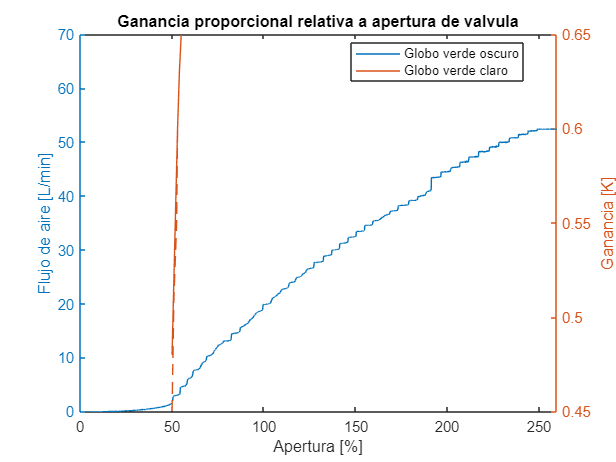

A=[50 51 52.5 53 54 55];
K1=[0.48 0.52 0.58 0.6 0.63 0.65];
AV=[50 51 52.5 53 54 55];
K2=[0.45 0.51 0.55 0.6 0.63 0.65];
plot(A,K1,AV,K2)
title('Ganancia proporcional relativa a apertura de valvula')
xlabel('Apertura [%]')
ylabel('Ganancia [K]')
legend('Globo verde oscuro','Globo verde claro')

K=polyfit(A,K1,1)

K =     0.0350   -1.2618


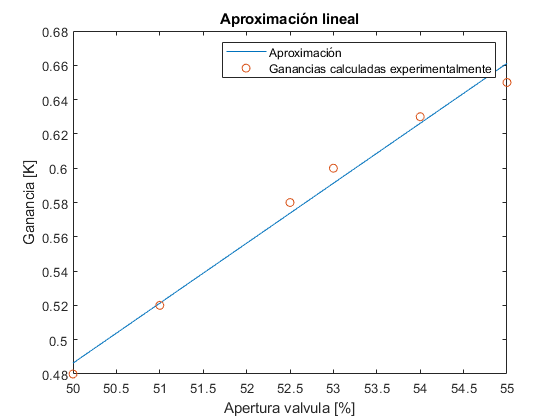

y=polyval(K,A);
figure
plot(A,y)
hold on
plot(A,K1,'o')
hold off
title('Aproximación lineal')
xlabel('Apertura valvula [%]')
ylabel('Ganancia [K]')
legend('Aproximación','Ganancias calculadas experimentalmente')